clear all;
close all;
clc;

% Number of simulations
num_sims = 10;

all_results = cell(num_sims, 1);

for i = 1:num_sims
    all_results{i} = Carp_Estimator('drop_altitude', 400, ... %alt_est
                                     'terrain_elevation', 560, ... 
                                     'ballistic_wind', 10, ...
                                     'drop_altitude_wind', 15, ...
                                     'dz_altimeter', 29.85, ...
                                     'surface_temperature', 20, ...
                                     'true_altitude_temperature', 15, ...
                                     'DZ_course', 302, ...
                                     'indicated_airspeed', 130, ...
                                     'num_parachutes', 1, ...
                                     'parachute_deploy_time', 3.38, ...
                                     'visualize', false);
    
   
    if mod(i, 10) == 0
        fprintf('Completed %d/%d simulations\n', i, num_sims);
    end
end

*** PARACHUTE DEPLOYED at t = 3.40 seconds ***
*** PARACHUTE DEPLOYED at t = 3.40 seconds ***
*** PARACHUTE DEPLOYED at t = 3.38 seconds ***
*** PARACHUTE DEPLOYED at t = 3.38 seconds ***
*** PARACHUTE DEPLOYED at t = 3.40 seconds ***
*** PARACHUTE DEPLOYED at t = 3.39 seconds ***
*** PARACHUTE DEPLOYED at t = 3.38 seconds ***
*** PARACHUTE DEPLOYED at t = 3.41 seconds ***
*** PARACHUTE DEPLOYED at t = 3.38 seconds ***
*** PARACHUTE DEPLOYED at t = 3.38 seconds ***


Completed 10/10 simulations




disp('Results structure:');

Results structure:


disp(all_results{1});

                      carp: [1×1 struct]
                propagator: [1×1 struct]
                time_error: -0.3547
        displacement_error: -13.0087
    displacement_error_pct: -2.5188
        descent_rate_error: 2.3671
    descent_rate_error_pct: 38.7797



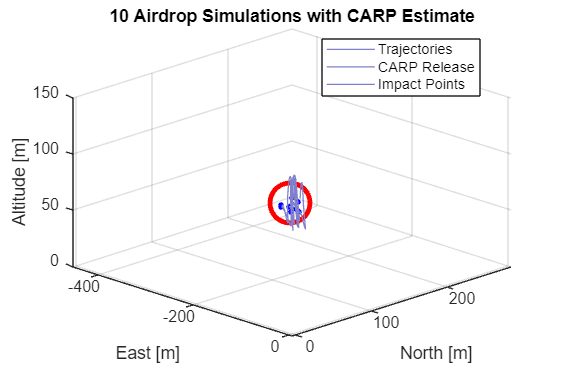


% Create 3D plot
figure('Position', [100, 100, 1200, 800]);
hold on;
grid on;

% Plot all drop trajectories
for i = 1:num_sims
    traj = all_results{i}.propagator.trajectory;
    plot3(traj(:,1), traj(:,2), traj(:,3), ...
          'Color', [0.5 0.5 0.8 0.3], 'LineWidth', 0.8);
end

% Plot CARP position (release point)
carp = all_results{1}.carp;
ftd_meters = carp.ftd * 0.9144;  % yards to meters
carp_east = ftd_meters * sind(carp.dz_heading);
carp_north = ftd_meters * cosd(carp.dz_heading);
carp_alt = carp.true_alt * 0.3048;  % feet to meters

plot3(carp_east, carp_north, 0, ...
      'ro', 'MarkerSize', 25, 'LineWidth', 3, 'DisplayName', 'CARP Landing Point');

% Plot all impact points
for i = 1:num_sims
    final_pos = all_results{i}.propagator.trajectory(end, :);
    plot3(final_pos(1), final_pos(2), final_pos(3), ...
          'b.', 'MarkerSize', 10);
end

xlabel('East [m]');
ylabel('North [m]');
zlabel('Altitude [m]');
title(sprintf('%d Airdrop Simulations with CARP Estimate', num_sims));
legend('Trajectories', 'CARP Release', 'Impact Points', 'Location', 'best');
view(45, 30);
hold off;


% Calculate impact statistics
all_impacts = zeros(num_sims, 3);
for i = 1:num_sims
    all_impacts(i, :) = all_results{i}.propagator.trajectory(end, :);
end
